# 测试

clc
clear
close all
addpath("src\");

n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [-2200., -8000., 100., 0., 0., 0.]';  % m, m/s
step = 1;

## 连续推力

### 间接法

tic
% [t, x] = CwIndirOpt(x0, n, tf, step, 'Riccati');
[t, x] = CwIndirOpt(x0, n, tf, step);
toc

历时 0.080169 秒。


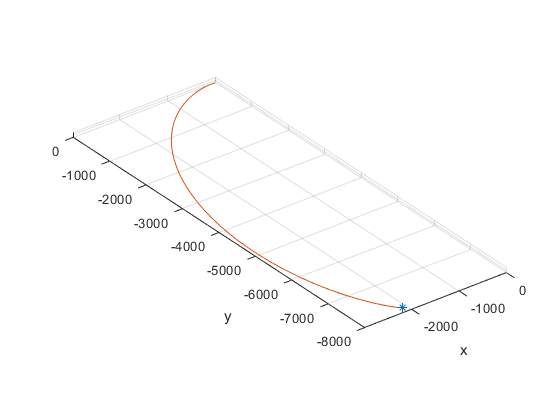

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on

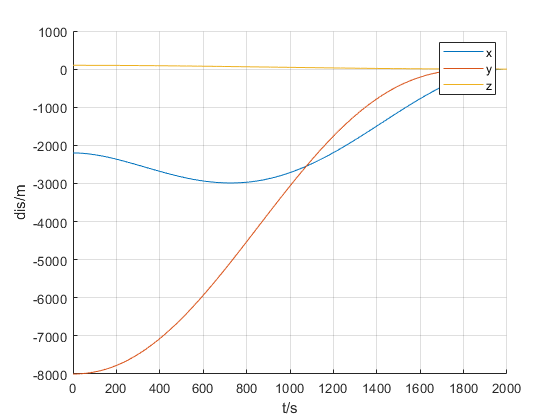

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

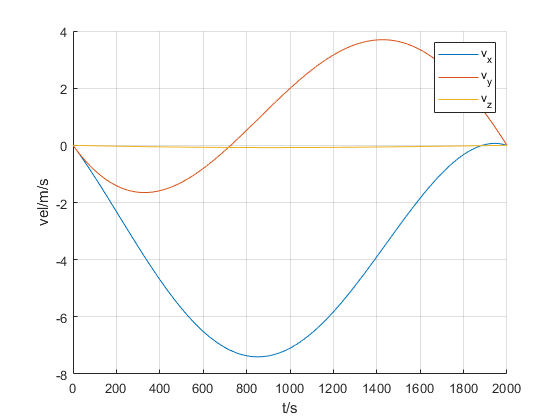

figure
hold on
plot(t, -x(:, 5))
plot(t, x(:, 4))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

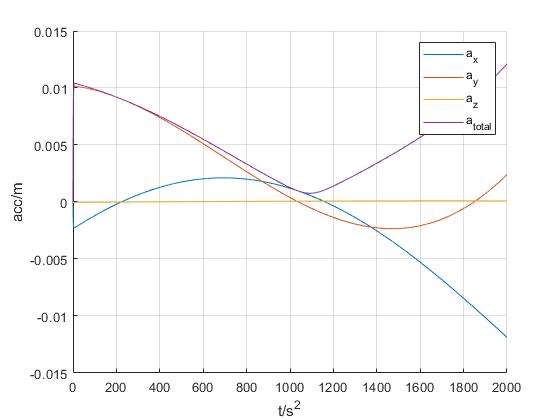

figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 11.3030

### 直接法

tic
[t, x] = CwDirOpt(x0, n, tf, step, 11);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

历时 33.930994 秒。


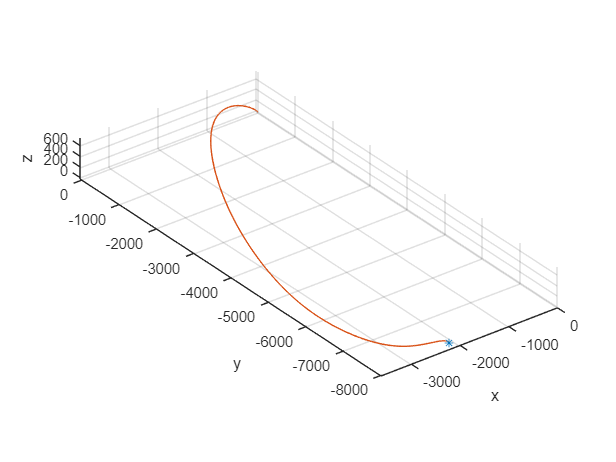

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on

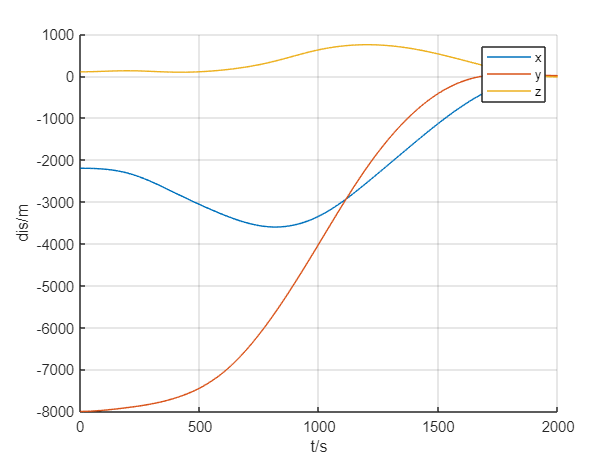

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

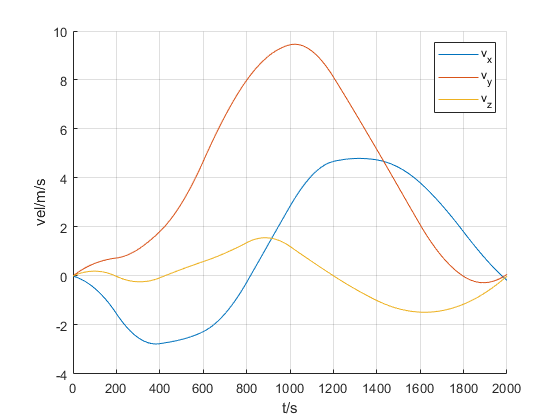

figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

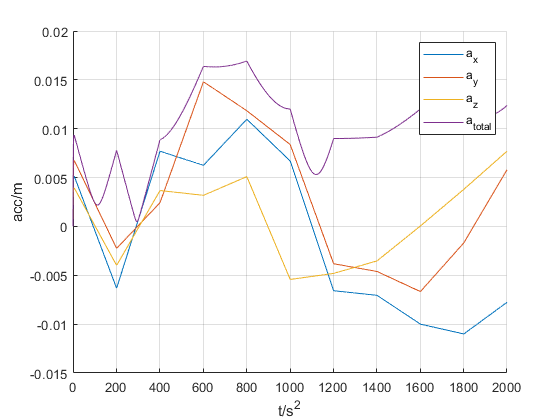

figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 20.2736

## 固定推力

x0 = [-2200., -8000., 100., 0., 0., 0.]';  % m, m/s
tf = 2000.; % s
n = 0.00111; % rad/s
tspan = 1;
f = 0.01; % m/s^2

### 间接法

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    8.404172e+01     9.683e+03     1.000e+00     0.000e+00     4.410e+03  
    1          16    5.764571e+01     9.041e+03     1.000e+00     4.688e-02     2.296e+11  
    2          26    2.478440e+01     5.972e+03     4.900e-01     7.875e+01     1.007e+12  
    3          39    5.729374e+00     4.190e+03     1.681e-01     2.038e+01     2.180e+12  
    4          54    1.190542e+01     4.024e+03     8.235e-02     8.307e+00     1.805e+12  
    5          65    1.877561e+01     3.675e+03     3.430e-01     5.856e+02     3.243e+11  
    6          76    2.456478e+01     2.340e+03     3.430e-01     2.326e+02     4.081e+11  
    7          88    1.168922e+01     2.157e+03     2.401e-01     1.070e+02     1.139e+12  
    8         103    6.907531e+00     1.703e+03     8.235e-02     6.676e+00     1.

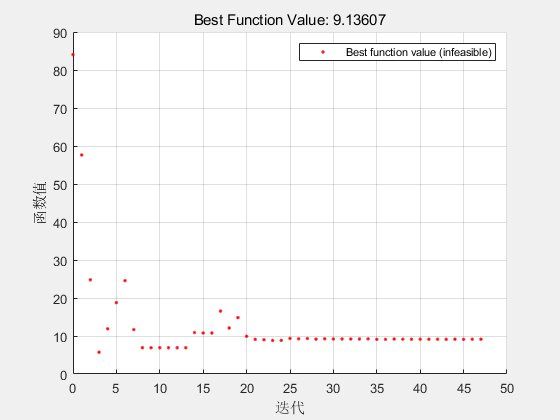


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x = 	1.0e+03 *

   -0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
    1.4835


fval = 9.1361

exitflag = -2

output = 包含以下字段的 struct :
         iterations: 47
          funcCount: 1401
          algorithm: 'sqp'
            message: '↵Converged to an infeasible point.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance but constraints are not↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-09, but the relative maximum constraint↵violation, 1.050945e-03, exceeds options.ConstraintTolerance = 1.000000e-07.↵↵'
    constrviolation: 10.1766
           stepsize: 1.0929e-06
       lssteplength: 2.1159e-09
      firstorderopt: 5.9452e+11
       bestfeasible: []


tic
[t, x] = CwIndirOpt2(x0, n, f, tf, tspan);

toc

历时 38.238312 秒。


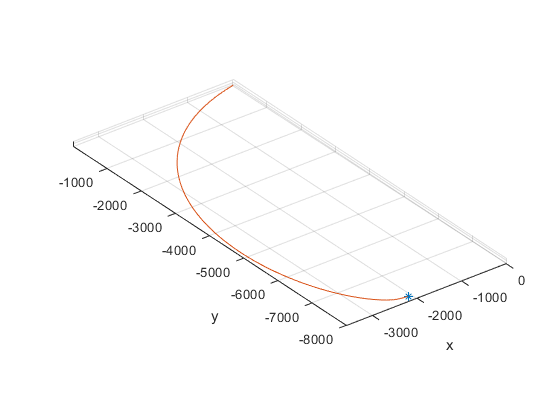

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on

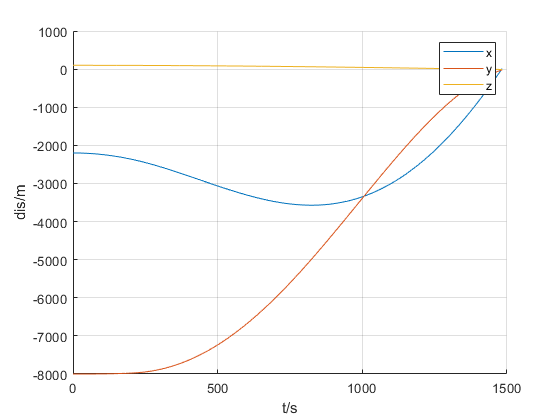

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

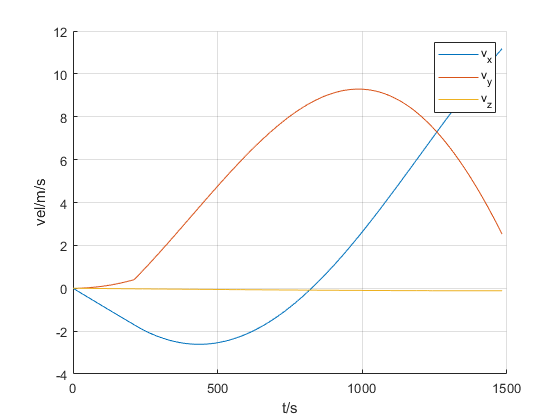

figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

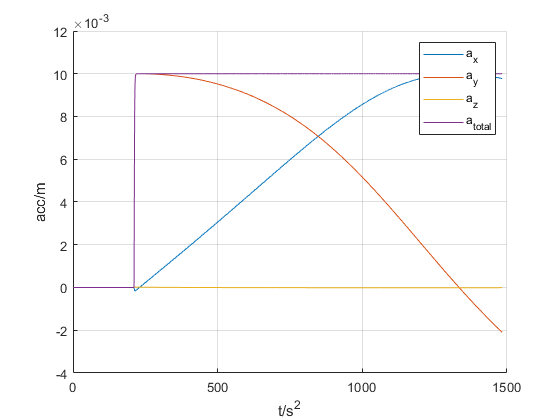

figure
hold on
plot(t, x(:, 13))
plot(t, x(:, 14))
plot(t, x(:, 15))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 13 : 15));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 17.1314